%% clear cache
clc;
clear variables;

%% set AudioFileManipulator class parameters
input_file_path = "vaiueo2d.wav";
output_file_path = "D:/名城大学/研究室/演習/data//LPC/synthesized_signal_by_LPCVocoder.wav";

%% generate AudioFileManipulator instance and confirm properties
audio_file_manipulator = AudioFileManipulator(input_file_path, output_file_path);
audio_file_manipulator.load_properties();
audio_file_manipulator.display_properties();

--------------------------------------------
---------- Audio File Manipulator ----------
input_file_path : vaiueo2d.wav
output_file_path : D:/名城大学/研究室/演習/data//LPC/synthesized_signal_by_LPCVocoder.wav
signal shape : (17500, 1)
sample_rate: 22050 [Hz]
             Filename: 'D:\名城大学\研究室\演習\MatlabPractice\SourceCode\Analysis\STRAIGHT\STRAIGHTV40_007b\vaiueo2d.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 22050
         TotalSamples: 17500
             Duration: 0.7937
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16

--------------------------------------------



%% generate LPCVocoder instance
lpc = LinearPredictiveCodingPitchExtractor(audio_file_manipulator.signal, audio_file_manipulator.information.SampleRate);
lpc.display_properties();

----------------------------------------------
-- Linear Predictive Coding Pitch Extractor --
signal size : (17500, 1)
window_mode : hamming
sample_rate : 22050 [Hz]
order : 30
voicing_threshold : 0.000100
frame_length : 706 [sample]
hop_length : 176 [sample]
basic_frequencies size : (99, 1)
basic_periods size : (99, 1)
----------------------------------------------



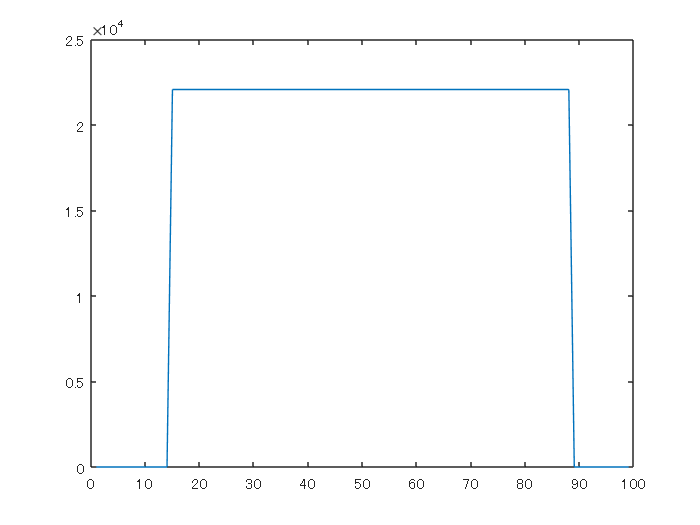

plot(lpc.basic_frequencies);